% =========================================================================
% 本科近代物理实验：热光场关联长度与双孔关联成像数据处理 (内置数据版)
% 风格要求：Physical Review A / Optics Letters
% =========================================================================
clear; clc; close all;

%% 全局绘图参数设置
set(0, 'DefaultAxesFontName', 'Times New Roman');
set(0, 'DefaultTextFontName', 'Times New Roman');
set(0, 'DefaultAxesFontSize', 12);
set(0, 'DefaultAxesLineWidth', 1.5);
set(0, 'DefaultLineLineWidth', 2);

%% ================= 图1：热光关联长度测量 =================
% 1. 内置清洗后的实验数据 [x, g2(x)]
data1 = [3,1.01694; 4,1.22705; 5,1.00036; 4.9,1.0012; 4.8,1.00244; ...
         4.7,1.00185; 4.6,1.00698; 4.5,1.01884; 4.4,1.03933; 4.3,1.06716; ...
         4.2,1.10951; 4.1,1.15981; 3.9,1.24882; 3.8,1.2794; 3.7,1.27544; ...
         3.6,1.24085; 3.5,1.19855; 3.4,1.14279; 3.3,1.1014; 3.2,1.06063; ...
         3.1,1.03597; 2.9,1.00677; 2.8,1.00151; 2.7,1.00118; 2.6,1.00226];
x1 = data1(:, 1);
y1 = data1(:, 2);

% 2. 单高斯拟合
% 公式: g2(x) = a*exp(-(x-b)^2/(2*c^2)) + d
ft1 = fittype('a*exp(-(x-b)^2/(2*c^2)) + d', 'independent', 'x', 'dependent', 'y');
opts1 = fitoptions('Method', 'NonlinearLeastSquares', 'StartPoint', [0.28, 3.8, 0.4, 1.0]);
[fitresult1, gof1] = fit(x1, y1, ft1, opts1);

% 提取并打印图1参数
a_fit = fitresult1.a; b_fit = fitresult1.b; c_fit = fitresult1.c; d_fit = fitresult1.d;
r2_1 = gof1.rsquare; g2_max = a_fit + d_fit;
fprintf('=== 图1：热光关联长度测量 拟合参数 ===\n');

=== 图1：热光关联长度测量 拟合参数 ===


fprintf('a = %.4f, b = %.4f, c = %.4f, d = %.4f\n', a_fit, b_fit, c_fit, d_fit);

a = 0.2797, b = 3.7656, c = 0.3211, d = 0.9998


fprintf('关联长度 c = %.4f mm, 峰值位置 b = %.4f mm, g2_max = %.4f, R2 = %.4f\n\n', c_fit, b_fit, g2_max, r2_1);

关联长度 c = 0.3211 mm, 峰值位置 b = 3.7656 mm, g2_max = 1.2795, R2 = 0.9987



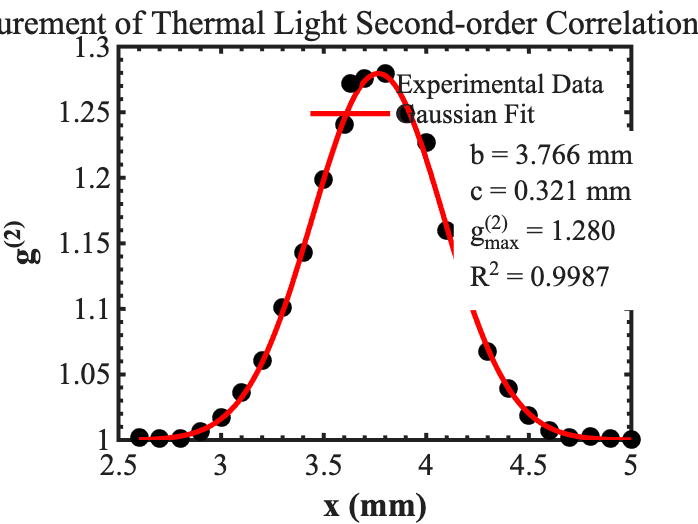


% 3. 绘制图1
fig1 = figure('Color', 'w', 'Position', [100, 100, 600, 450]);
plot(x1, y1, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 5, 'DisplayName', 'Experimental Data');
hold on;
x_fit1 = linspace(min(x1), max(x1), 500)';
plot(x_fit1, fitresult1(x_fit1), 'r-', 'DisplayName', 'Gaussian Fit');

xlabel('x (mm)', 'FontWeight', 'bold'); ylabel('g^{(2)}', 'FontWeight', 'bold');
title('Measurement of Thermal Light Second-order Correlation Function');
set(gca, 'Box', 'on', 'TickDir', 'in', 'XMinorTick', 'on', 'YMinorTick', 'on');
grid off; set(gca, 'GridLineStyle', '--', 'GridAlpha', 0.3);

str1 = sprintf('b = %.3f mm\nc = %.3f mm\ng^{(2)}_{max} = %.3f\nR^2 = %.4f', b_fit, c_fit, g2_max, r2_1);
annotation('textbox', [0.65, 0.55, 0.2, 0.2], 'String', str1, 'FitBoxToText', 'on', ...
    'BackgroundColor', 'w', 'EdgeColor', 'none', 'FontName', 'Times New Roman', 'FontSize', 11);
legend('Location', 'northeast', 'Box', 'off');
exportgraphics(fig1, 'Figure1_Correlation_Length.png', 'Resolution', 300);


%% ================= 图2：双孔热光关联成像 =================
% 1. 内置清洗后的实验数据 [x, g2(x)]
data2 = [0,1.03832; 0.1,1.03732; 0.2,1.03776; 0.3,1.03976; 0.4,1.03751; 0.5,1.0394; ...
         0.6,1.03778; 0.7,1.03825; 0.8,1.03436; 0.9,1.02975; 1,1.02654; 1.1,1.0203; ...
         1.2,1.01909; 1.3,1.01267; 1.4,1.00901; 1.5,1.00551; 1.6,1.0031; 1.7,1.00304; ...
         1.8,1.00409; 1.9,1.00087; 2,1.00248; 2.1,1.00017; 2.2,1.00098; 2.3,1.00008; ...
         2.4,0.997003; 2.5,0.999722; 2.6,0.99931; 2.7,1.00089; 2.8,0.99984; 2.9,0.999903; ...
         3,1.00089; 3.1,1.00169; 3.2,1.00089; 3.3,1.00173; 3.4,1.00093; 3.5,1.00287; ...
         3.6,1.00172; 3.7,1.0025; 3.8,1.00457; 3.9,1.00718; 4,1.00856; 4.1,1.01008; ...
         4.2,1.01295; 4.3,1.01538; 4.4,1.0206; 4.5,1.02438; 4.6,1.02667; 4.7,1.02855; ...
         4.8,1.03188; 4.9,1.02993; 5,1.03014; 5.1,1.03234; 5.2,1.03235; 5.3,1.03024; ...
         5.4,1.03097; 5.5,1.03048; 5.6,1.02969; 5.7,1.03191; 5.8,1.03355; 5.9,1.02947; ...
         6,1.02846; 6.1,1.02696; 6.2,1.02504; 6.3,1.02006; 6.4,1.01981; 6.5,1.01837; ...
         6.6,1.01368; 6.7,1.01083; 6.8,1.01224; 6.9,1.00766; 7,1.00634; 7.1,1.0042; ...
         7.2,1.00509; 7.3,1.00364; 7.4,1.00138; 7.5,1.00098; 7.6,1.00139; 7.7,1.00233; ...
         7.8,1.00194; 7.9,1.0017; 8,1.002; -0.1,1.03474; -0.2,1.03189; -0.3,1.03521; ...
         -0.4,1.03382; -0.5,1.03425; -0.6,1.03453; -0.7,1.03148; -0.8,1.03245; ...
         -0.9,1.03002; -1,1.02866; -1.1,1.02581; -1.2,1.02401; -1.3,1.01905; ...
         -1.4,1.01711; -1.5,1.01228; -1.6,1.00906; -1.7,1.00601; -1.8,1.00525; ...
         -1.9,1.00447; -2,1.00301; -2.1,1.00211; -2.2,1.0014; -2.3,1.00224; -2.4,1.00078];
x2 = data2(:, 1);
y2 = data2(:, 2);

% 2. 双高斯拟合
% 公式: g2(x) = a1*exp(-(x-b1)^2/(2*c1^2)) + a2*exp(-(x-b2)^2/(2*c2^2)) + d
ft2 = fittype('a1*exp(-(x-b1)^2/(2*c1^2)) + a2*exp(-(x-b2)^2/(2*c2^2)) + d', 'independent', 'x', 'dependent', 'y');
opts2 = fitoptions('Method', 'NonlinearLeastSquares', ...
    'StartPoint', [0.04, 0.03, 0.4, 5.5, 0.5, 0.5, 1.0], ...
    'Lower', [0, 0, -2, 3, 0.1, 0.1, 0.9], ...
    'Upper', [0.2, 0.2, 2, 8, 2, 2, 1.1]);
[fitresult2, gof2] = fit(x2, y2, ft2, opts2);

% 提取并打印图2参数
b1_fit = fitresult2.b1; b2_fit = fitresult2.b2; delta_x = abs(b2_fit - b1_fit); r2_2 = gof2.rsquare;
fprintf('=== 图2：双孔热光关联成像 拟合参数 ===\n');

=== 图2：双孔热光关联成像 拟合参数 ===


fprintf('a1 = %.4f, b1 = %.4f, c1 = %.4f\n', fitresult2.a1, fitresult2.b1, fitresult2.c1);

a1 = 0.0436, b1 = -0.0361, c1 = 1.0295


fprintf('a2 = %.4f, b2 = %.4f, c2 = %.4f\n', fitresult2.a2, fitresult2.b2, fitresult2.c2);

a2 = 0.0367, b2 = 5.4091, c2 = 1.0049


fprintf('d = %.4f\n', fitresult2.d);

d = 0.9968


fprintf('第一峰 b1 = %.4f mm, 第二峰 b2 = %.4f mm\n', b1_fit, b2_fit);

第一峰 b1 = -0.0361 mm, 第二峰 b2 = 5.4091 mm


fprintf('峰间距 delta_x = %.4f mm, R2 = %.4f\n', delta_x, r2_2);

峰间距 delta_x = 5.4452 mm, R2 = 0.9624


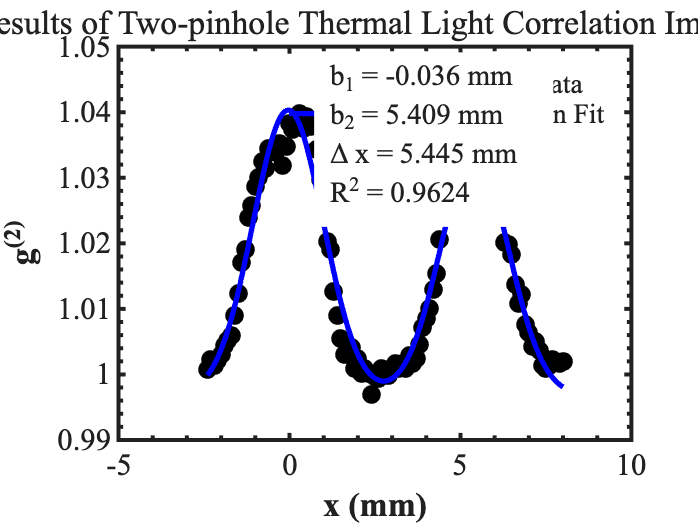


% 3. 绘制图2
fig2 = figure('Color', 'w', 'Position', [150, 150, 600, 450]);
plot(x2, y2, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 5, 'DisplayName', 'Experimental Data');
hold on;
x_fit2 = linspace(min(x2), max(x2), 500)';
plot(x_fit2, fitresult2(x_fit2), 'b-', 'DisplayName', 'Double-Gaussian Fit');

xlabel('x (mm)', 'FontWeight', 'bold'); ylabel('g^{(2)}', 'FontWeight', 'bold');
title('Results of Two-pinhole Thermal Light Correlation Imaging');
set(gca, 'Box', 'on', 'TickDir', 'in', 'XMinorTick', 'on', 'YMinorTick', 'on');
grid off; set(gca, 'GridLineStyle', '--', 'GridAlpha', 0.3);

str2 = sprintf('b_1 = %.3f mm\nb_2 = %.3f mm\n\\Delta x = %.3f mm\nR^2 = %.4f', b1_fit, b2_fit, delta_x, r2_2);
annotation('textbox', [0.45, 0.70, 0.2, 0.2], 'String', str2, 'FitBoxToText', 'on', ...
    'BackgroundColor', 'w', 'EdgeColor', 'none', 'FontName', 'Times New Roman', 'FontSize', 11);
legend('Location', 'northeast', 'Box', 'off');
exportgraphics(fig2, 'Figure2_Two_Pinhole.png', 'Resolution', 300);


fprintf('\n==== 运行完毕！图像已在当前文件夹保存为高分辨率 png 文件 ====\n');


==== 运行完毕！图像已在当前文件夹保存为高分辨率 png 文件 ====
